Preparando la simulación del modelo

func='SIRSemillero'; %Nombre del archivo del modelo
ranges=[800 1000;0 100; 0 500; 0 1;0 1; 0 1]; %Intervalos para los parámetros del modelo
names = {'S_0','I_0','R_0','\beta','\gamma','\alpha'}; %Nombres de los parámetros del modelo
out_names = {'S(t)','I(t)','R(t)'}; %Nombres de las salidas del modelo
nominal=[900,10,100,0.5,0.1,0.01]; %valores de simulación nominal (no es necesario)
domain=[0, 30];%Dominio de simulación
copt = struct; %Se transforma en in al interior del modelo
copt.alpha=ones(1,domain(2)-domain(1))*0.3; %creamos series de tiempo que se usan al interior del modelo
T = gsua_dataprep(func,ranges,'domain',domain,'names',names,'out_names',out_names,'nominal',nominal,'opt',copt);

Setting environment to work with user-defined function


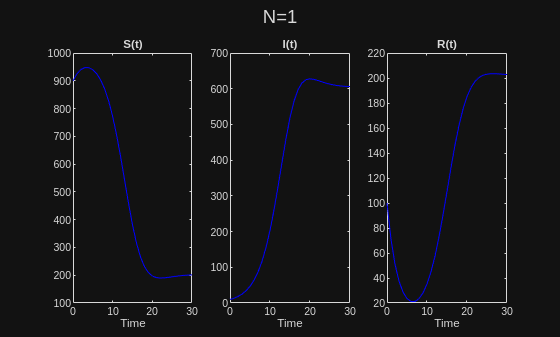

Y=gsua_eval(T.Nominal,T);

Seleccionando salidas del modelo:

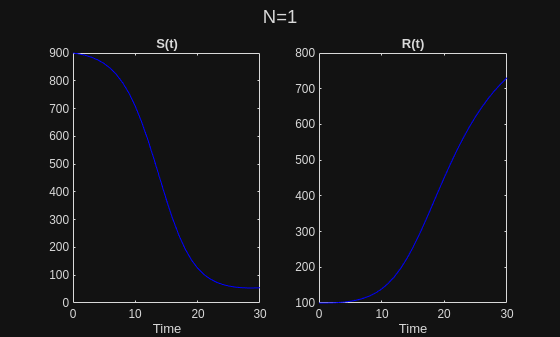

T.Properties.CustomProperties.output=[1,3];
Y=gsua_eval(T.Nominal,T);

Análisis de incertidumbre

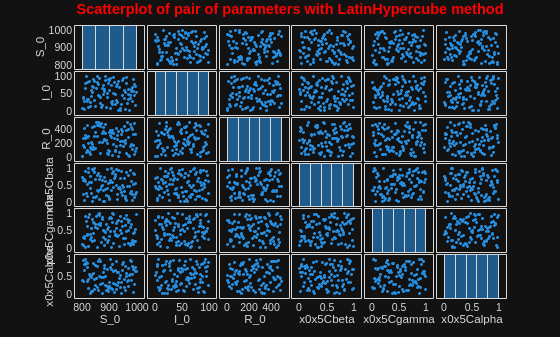

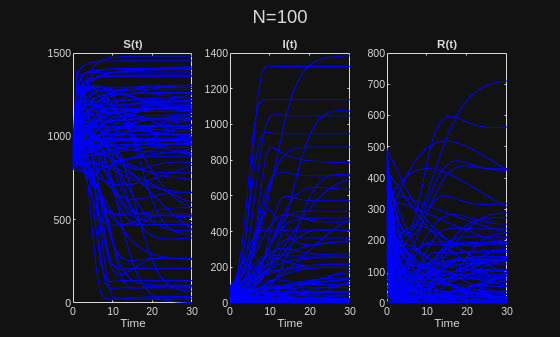

T.Properties.CustomProperties.output=[1,2,3]; %Todas las salidas del modelo
M=gsua_dmatrix(T,100,'Show','on');%Matriz de exploración del espacio de factores
Y=gsua_eval(M',T);%Evaluación de la matriz

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:22:1
Number of simulations: 100


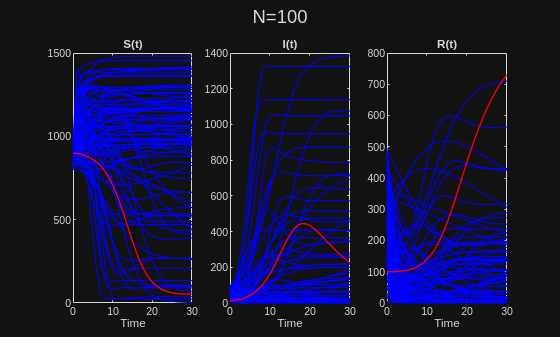

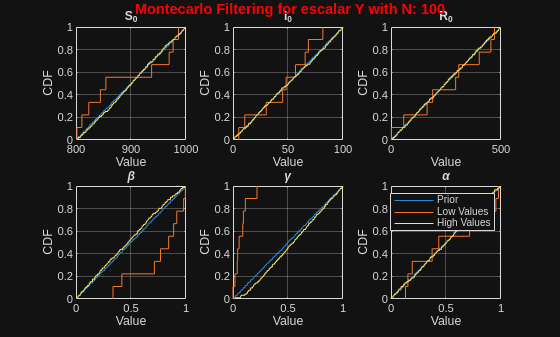

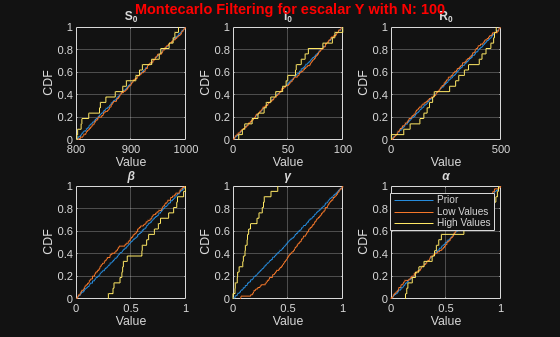

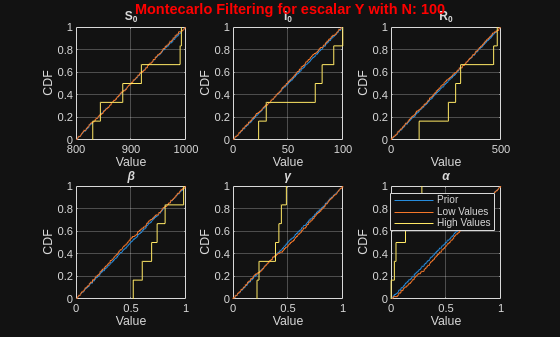

Y=gsua_ua(M,T,'parallel',false); %Análisis de incertidumbre + filtro de MonteCarlo

Estimación de parámetros:

Vamos a generar una curva de datos que usaremos como "reales" para luego tratar de conseguir los parámetros que la generaron.

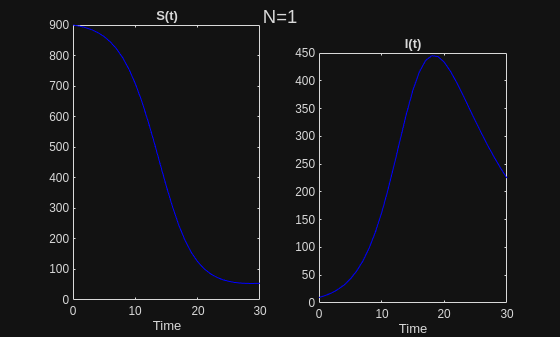

T.Properties.CustomProperties.output=[1,2]; %Escoger salidas del modelo
Y=gsua_eval(T.Nominal,T);

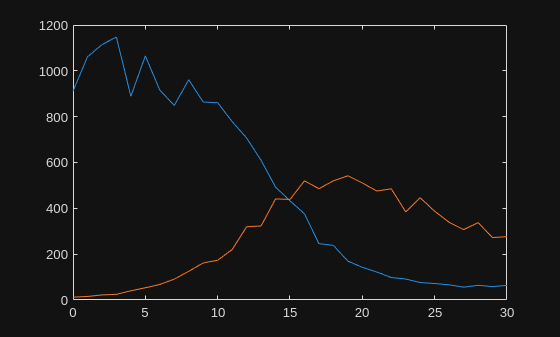

if size(Y,3)>1
    ydata=squeeze(Y)'; %Extraemos las curvas
else
    ydata=Y;
end
ydata = ydata + 0.3*rand(size(ydata,1),size(ydata,2)).*ydata; %adicionamos ruido
xdata=0:30; %Especificamos los puntos del tiempo a los que corresponde el muestreo
figure(1) %creamos una figura
clf
plot(xdata,ydata)

Antes de proceder directamente a la estimación de parámetros vale la pena comprobar que las curvas a estimar se encuentran en el espacio solución del modelo

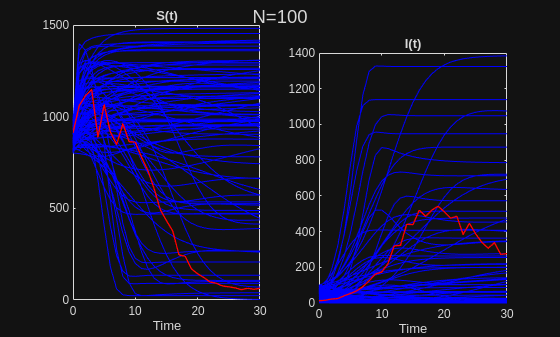

gsua_eval(M',T,xdata,ydata);

Ahora sí procedemos como tal con la estimación de parámetros

Generating a valid matrix for estimations
Estimation 1

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>
Progress: 1%
Estimated processing time (h:m:s): 0:0:5
Remaining time (h:m:s): 0:0:5
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:22:11
Number of simulations: 100
Estimation 2

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the <a href 

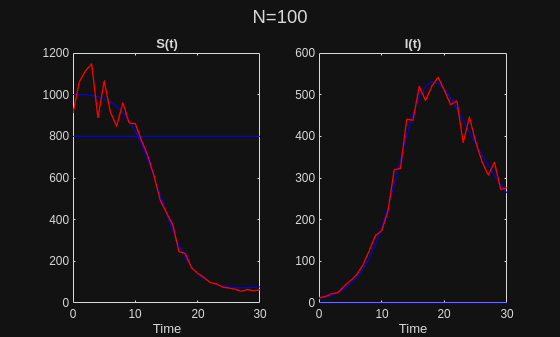

Te = 6×3 table
                 Range       Nominal      Estlsqc   
              ___________    _______    ____________

    S_0       800    1000      900      1×100 double
    I_0         0     100       10      1×100 double
    R_0         0     500      100      1×100 double
    \beta       0       1      0.5      1×100 double
    \gamma      0       1      0.1      1×100 double
    \alpha      0       1     0.01      1×100 double


costVals = 1.0e+07 *

    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099


[Te, costVals] = gsua_pe(T,xdata,ydata,'N',100,'show','on')%Hacemos la estimación de parámetros y pedimos las funciones de costo

Análisis de sensibilidad

M = gsua_dmatrix(T,1000);%Nueva matriz de diseño con mayor muestreo
T.Properties.CustomProperties.output=2;%Nos quedamos con solo 1 salida (Es mejor para interpretaciones)
Tsa = gsua_sa(M,T,'parallel',false);%Análisis de sensibilidad

Progress: 13%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:22:8
Number of simulations: 4000
Progress: 25%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:22:8
Number of simulations: 4000
Progress: 38%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:22:8
Number of simulations: 4000
Progress: 50%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:22:8
Number of simulations: 4000
Progress: 63%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 17:22:8
Number of simulations: 4000
Progress: 75%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0

Visualización de resultados del análisis de sensibilidad

- `gsua_plot('UncertaintyAnalysis',T,Y,xdata,ynom); ``<- Uncertainty analysis graph`

- `gsua_plot('ScatterOutput',T,Y,M,xdata,xref); ``<- Uncertainty analysis for output in time=xref`

- `gsua_plot('ScatterOutput',T,J,M,xdata); ``<- Uncertainty analysis for scalar output (MSE of the output with respecto to ynom)`

- `gsua_plot('Pie',T,T.STi/Si); ``<- Pie graph of sensitivity indices`

- `gsua_plot('Bar',T,T.STi/Si); ``<- Bar graph of sensitivity indices`

- `gsua_plot('FractionalSensitivityArea',T,T.STi_vec/Si_vec,xdata); ``<- Area graph of vectorial sensitivity indices (a index for each point in xdata)`

- `gsua_plot('TotalSensitivityArea',T,T.STi_vec/Si_vec,xdata); ``<- Normalized area graph of vectorial sensitivity indices (a index for each point in xdata)`

- `gsua_plot('FractionalSensitivityPlots',T,T.STi_vec/Si_vec,xdata); ``<- Figure of subgraphs with the sensitivity indices plot for each factor, and for each point in xdata.`

- `gsua_plot('Pie',T,T.STi_vec/Si_vec,xdata,[t1,t2,t3,t4]); ``<- Figure of pie subgraphs. As many subgraphs as points in [t1,t2,...tn]. Each pie represent the sensitivity indices for a specific time [t1,t2,...tn].`

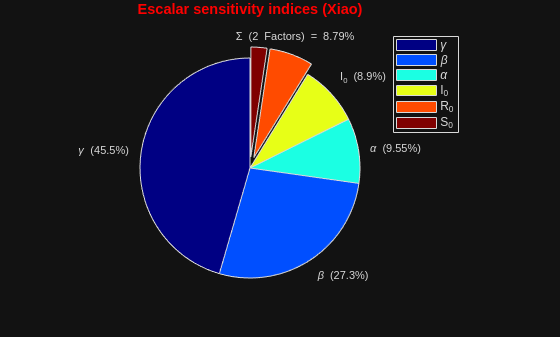

figure(1)
clf
gsua_plot('Pie',Tsa,Tsa.STi);

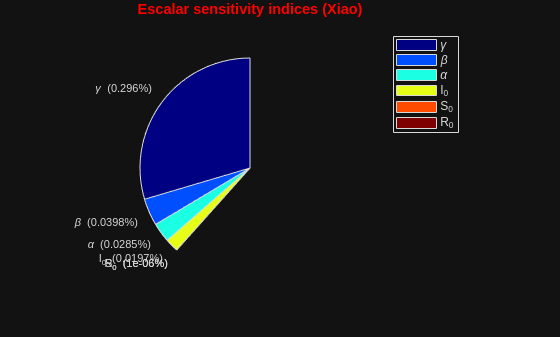

figure(2)
clf
gsua_plot('Pie',Tsa,Tsa.Si);

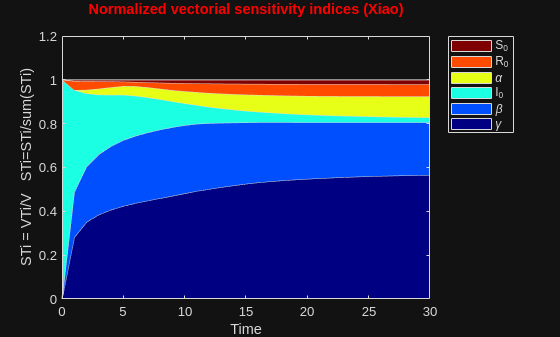

figure(3)
clf
gsua_plot('TotalSensitivityArea',Tsa,Tsa.STi_vec,xdata); 

Análisis de identificabilidad

Vale la pena primero graficar las funciones de costo para quedarse con las mejores (Están ordenadas de menor a mayor)

figure(4)
clf
thr = costVals(1)*1.3;
length(costVals(costVals<thr))%Número de curvas seleccionadas

ans = 94

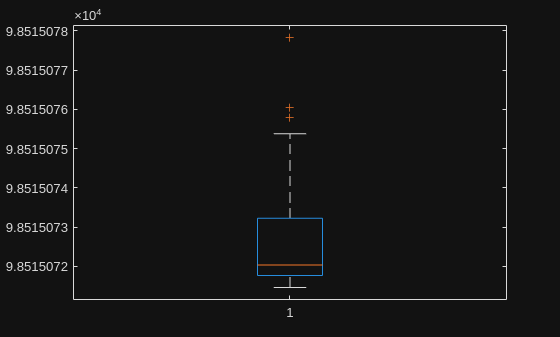

boxplot(costVals(costVals<thr))

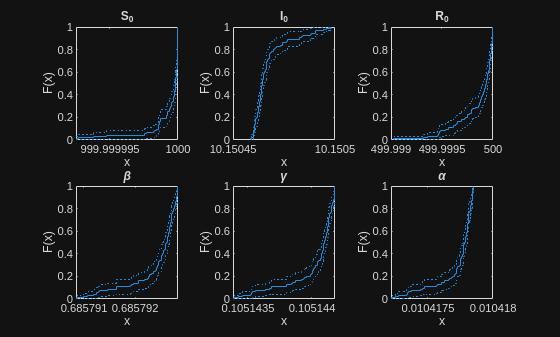

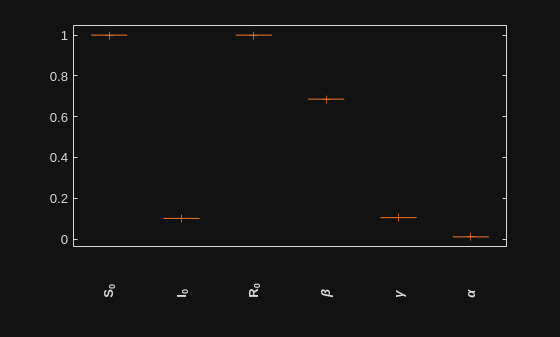

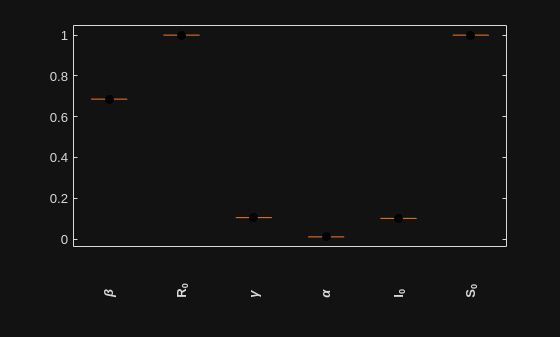

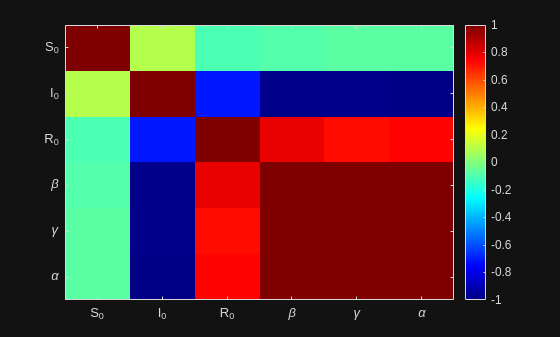

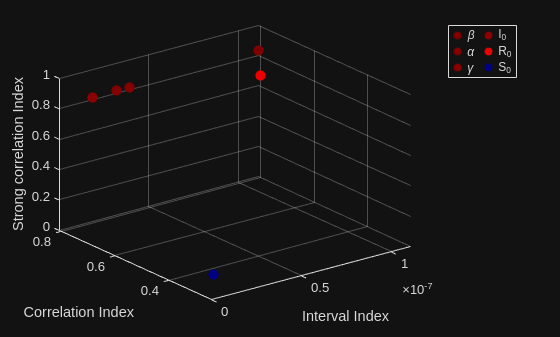

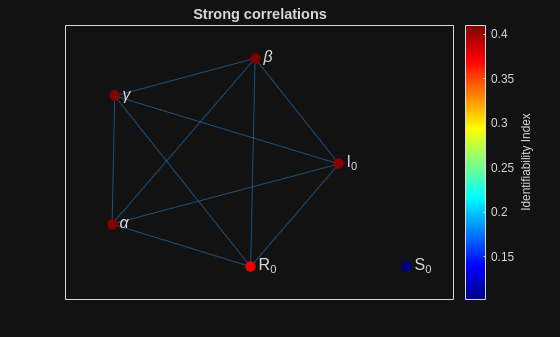

T = 6×5 table
                     Range            Nominal       Estlsqc           Est         index 
              ____________________    ________    ____________    ___________    _______

    S_0           1000        1000        1000    1×100 double    1×94 double    0.10146
    I_0          10.15       10.15       10.15    1×100 double    1×94 double     0.4061
    R_0            500         500         500    1×100 double    1×94 double    0.37719
    \beta      0.68579     0.68579     0.68579    1×100 double    1×94 double    0.41027
    \gamma     0.10514     0.10514     0.10514    1×100 double    1×94 double    0.40707
    \alpha    0.010418    0.010418    0.010418    1×100 double    1×94 double    0.40803


Tia = gsua_ia(Te,Te.Estlsqc(:,costVals<thr),true,false,true);